% inputSize = trainedNetwork.Layers(1).InputSize;
% path = '/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/231003_ファイバー簡略化/分類用画像/3秒間隔_image';
load trainedNetwork_without100.mat;
path = "/Users/daiki_daiku/Documents/Univ";
path = fullfile(path,"pi");
I = imageDatastore(path,"IncludeSubfolders",true,"LabelSource","foldernames");
% I=imageDatastore('C:\Users\daikidaiku\Box\Personal\study\Data\2023\231003_ファイバー簡略化\分類用画像\3秒間隔_image',...
%     "IncludeSubfolders",true,"LabelSource","foldernames")
% type=readcell("/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/研究/230117/type.xlsx")

% trainedNetwork = st_alex;
trainedNetwork = pi_alex;
% trainedNetwork = st_Google;
inputSize = trainedNetwork.Layers(1).InputSize;

% n=type(2:5,4);
% m=repelem(n,55); % 繰り返し
p=I.Labels;

I.Labels=p;

[imdsTrain, imdsValidation] = splitEachLabel(I,0.7,"randomized");
Im = augmentedImageDatastore(inputSize,imdsValidation);
I_total = augmentedImageDatastore(inputSize,I);
YTest = classify(trainedNetwork,I_total);
% YTest = classify(trainedNetwork,Im);
figure;

% c=imdsValidation.Labels;
c = I.Labels;


YTest = renamecats(YTest,{'Defect A','Defect B',...
    'Defect C','Defect D','No Defect'});
c = renamecats(c,{'Defect A','Defect B',...
    'Defect C','Defect D','No Defect'});
YTest(500) = "No Defect";
YTest(501) = "No Defect";
YTest(502) = "No Defect";
YTest(503) = "No Defect";

cm=confusionchart(c,YTest);
cm.FontSize=22;
xlabel('Predict Values')
ylabel('Actual Values')
missed_AC = [];
missed_CB = [];
missed_DC = [];
missed_AD = [];
missed_BN = [];
missed_CN = [];
count = length(c);
for i = 1 : length(c)
    if c(i) ~= YTest(i)
        
        count = count - 1;
        
        if c(i) == "Defect A" && YTest(i) == "Defect C"
            missed_AC = [missed_AC; I.Files(i)];
        end
        if c(i) == "Defect C" && YTest(i) == "Defect B"
            missed_CB = [missed_CB; I.Files(i)];
        end
        if c(i) == "Defect D" && YTest(i) == "Defect C"
            missed_DC = [missed_DC; I.Files(i)];
        end
        if c(i) == "Defect A" && YTest(i) == "Defect D"
            missed_AD = [missed_AD; I.Files(i)];
        end
        if c(i) == "Defect B" && YTest(i) == "No Defect"
            missed_BN = [missed_BN; I.Files(i)];
        end
        if c(i) == "Defect C" && YTest(i) == "No Defect"
            missed_CN = [missed_CN; I.Files(i)];
        end
        % c(i)j
        % YTest(i)
    end
end
count;
accuracy = (count) / length(c)

accuracy = 0.9978

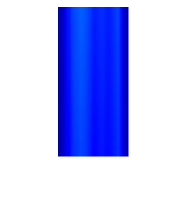

% res = missed_AC;


% res = missed_CB;
% 
% res = missed_DC;
% 
% res = missed_AD;
% 
res = missed_BN;
% 
% res = missed_CN;
imshow(res{2})


ax = gca;
copygraphics(ax,'Resolution',300)

% % I_of_parts =imageDatastore(fullfile(path,"A/"));
% % montage(I_of_parts)
% % I_of_parts =imageDatastore(fullfile(path,"B/"));
% % montage(I_of_parts)
% % I_of_parts =imageDatastore(fullfile(path,"C/"));
% % montage(I_of_parts)
% % I_of_parts =imageDatastore(fullfile(path,"D/"));
% % montage(I_of_parts)
% % I_of_parts =imageDatastore(fullfile(path,"/None/"));
% % montage(I_of_parts)

c;
YTest;
mistake = {};
% a = c == YTest;
% for i = 1:length(a)
%     if a(i) == 0
%         imdsValidation.Files{i,1}
%         c(i)
%         YTest(i)
%         predict(i,trainedNetwork)
%     end
% end


% cm=confusionchart(matrixForValidationData, truePredictedLabelsForValidation);
% cm.FontSize=22;
% xlabel('予測した状態')
% ylabel('実際の状態')